% load colour_allvar_m__1_tau_1.mat

% figure
% hold on
% % dh = 0.01;
% % x = 0:dh:1.5;
% % pdKern = fitdist(tt21', 'kernel')
% % p21 = pdf(pdKern, x)
% plot(x,p21,'LineWidth', 2)
% h21 = histogram(tt21,'Normalization','pdf')
% hold off
% xlabel("{\Delta t_m}")
% ylabel("pdf")

%contour plot
%x1 = [0 0.05:0.01:0.1 0.15:0.05:0.95];
x1 = 0:0.05:1

x1 =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


y1 = 0:0.01:1.5;
%Z = [p0' p1' p_1' p_2' p_3' p_4' p2' p3' p4' p6' p5' p7' p8' p9' p10' p11' p12' p13' p14' p15' p16' p17' p18' p19'];
Z = [p1' p2' p3' p4' p5' p6' p7' p8' p9' p10' p11' p12' p13' p14' p15' p16' p17' p18' p19' p20' p21'];
[X,Y] = meshgrid(x1,y1);
figure
%plot3(X,Y,Z)
%figure
%surf(X,Y,Z, 'edgecolor', 'none')
contourf(X,Y,Z,50, 'edgecolor', 'none')
shading interp;
colormap jet;
%xlim([0 1.0])
%ylim([0.2,1.2])
xlabel ('A','interpreter','latex')
ylabel ('$\tau$','interpreter','latex')
title('m = 1; correlation time = 1/f', 'FontName','Times', 'FontSize', 12)
axis()

ans =          0    1.0000         0    1.5000


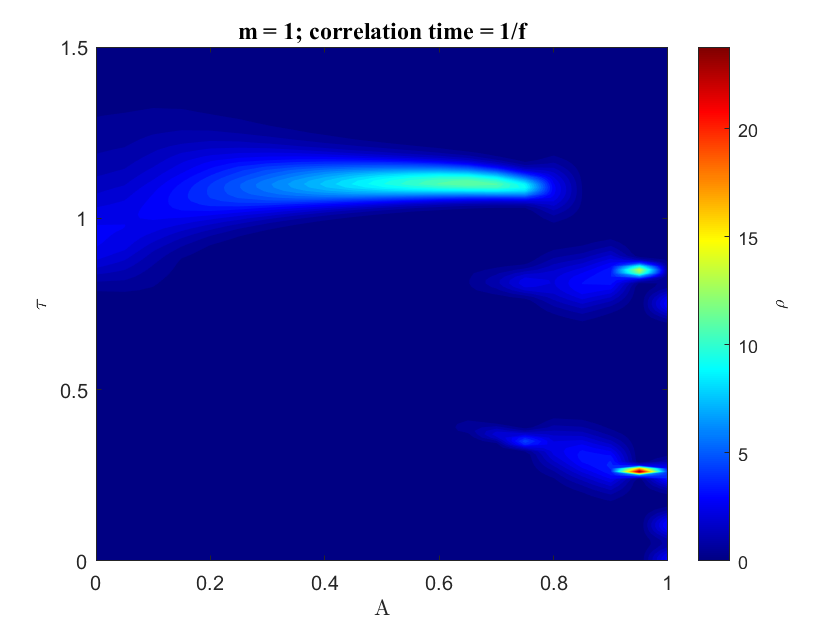

a = colorbar;
a.Label.String = '\rho';